*Prepared by *

*Asif Newaz*

*Lecturer, EEE, IUT*

This lab covers generation and visualization of different waveforms.

**Sine wave**

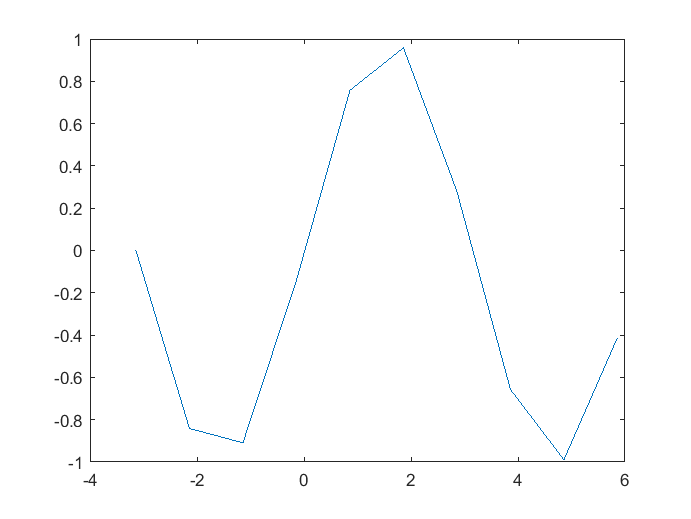

x= -pi:2*pi; 
y= sin(x);
plot(x,y)

You need to increase the number of samples in between to generate a more clear sine wave. Here, the step size is 1 (default value).

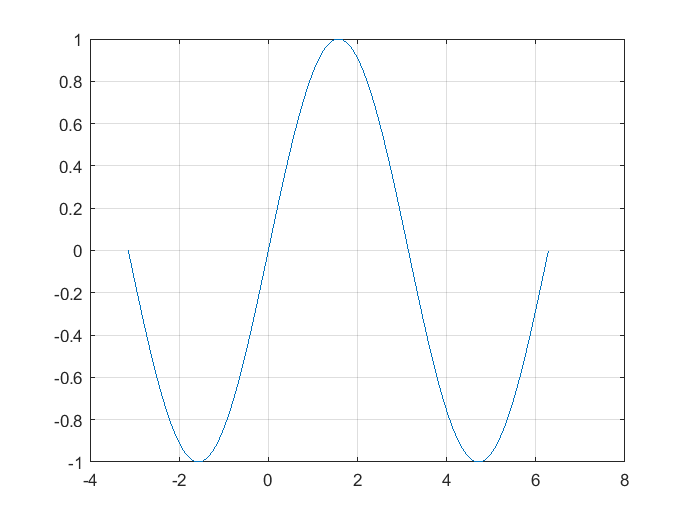

x= -pi:0.001:2*pi; 
y= sin(x);
plot(x,y)
grid on

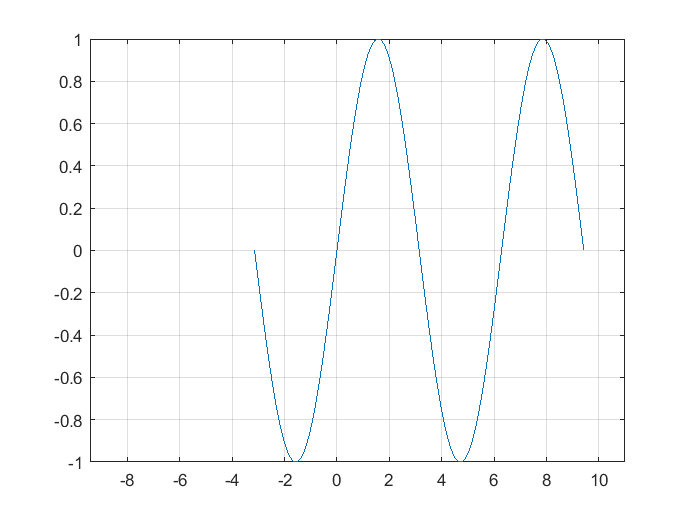

x= -pi:0.001:3*pi; 
y= sin(x);
plot(x,y)
axis([-3*pi, 3.5*pi, -1,1])
grid on

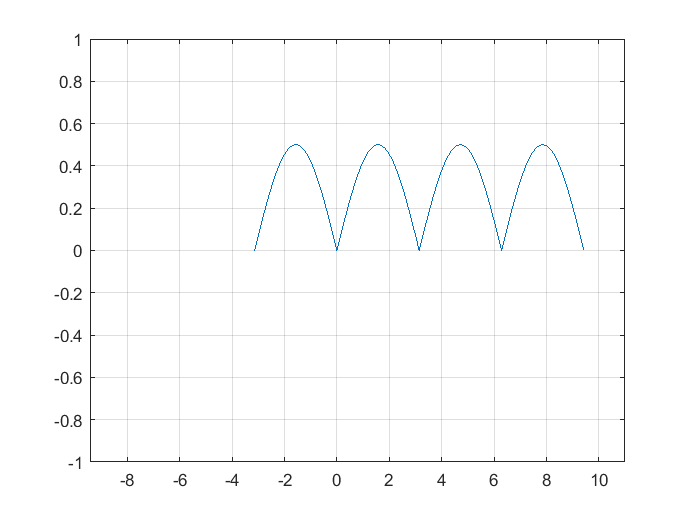

x= -pi:0.001:3*pi; 
y= 0.5* abs(sin(x));
plot(x,y)
axis([-3*pi, 3.5*pi, -1,1])
grid on

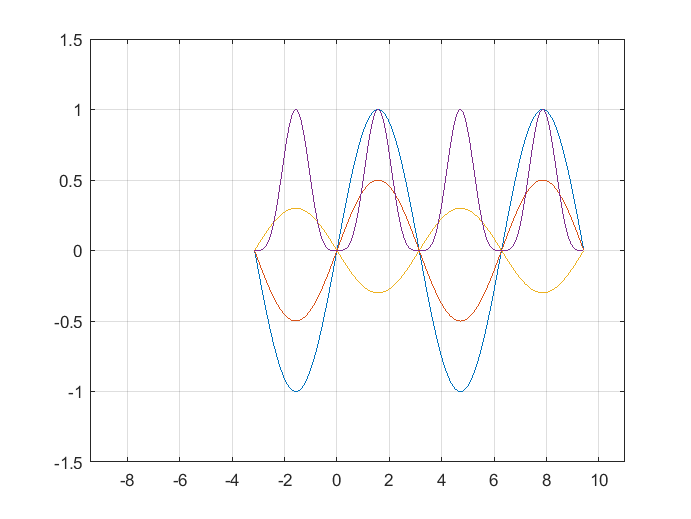

x= -pi:0.001:3*pi; 
y= sin(x);
plot(x,y,x,0.5*sin(x),x,-0.3*y,x,y.^4)
axis([-3*pi, 3.5*pi, -1.5,1.5])
grid on

**Square Wave**

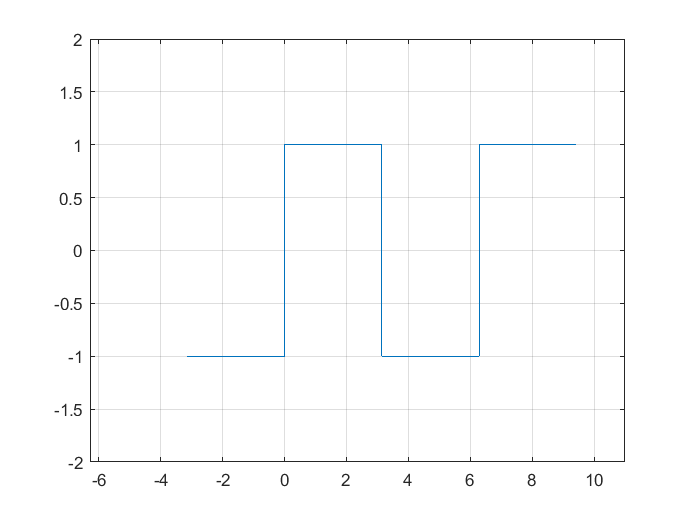

x= -pi:0.001:3*pi;
y= square(x);
plot(x,y)
axis([-2*pi, 3.5*pi, -2,2])
grid on

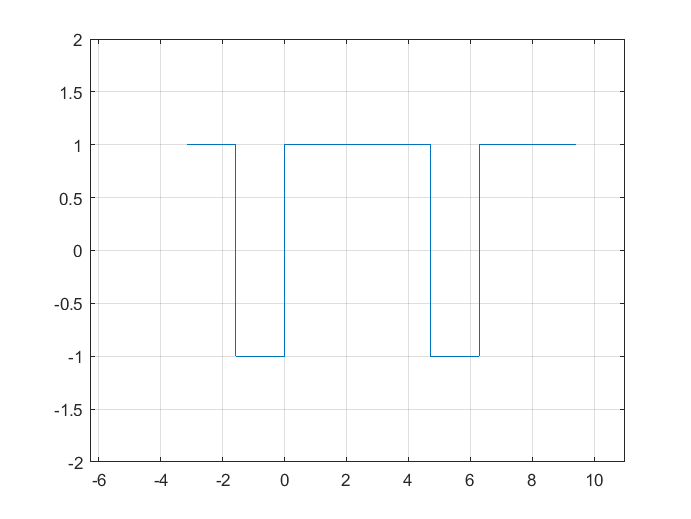

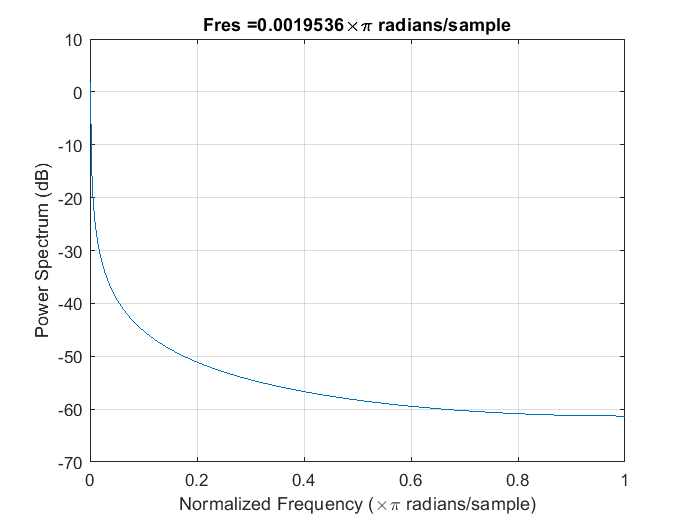

y= square(x, 75); % the second parameter is the duty cycle; value ranging from 0 to 100.
plot(x,y)
axis([-2*pi, 3.5*pi, -2,2])
grid on

You can also plot two waves together in the same figure

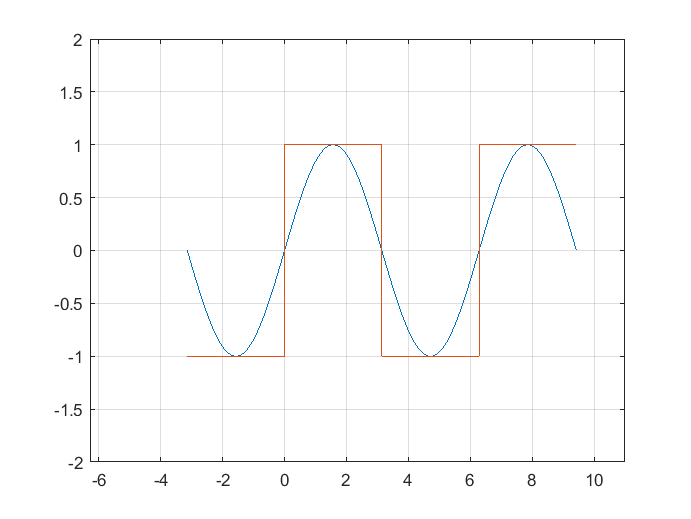

x= -pi:0.001:3*pi;
plot(x,sin(x))
hold on
plot(x, square(x))
hold off
axis([-2*pi, 3.5*pi, -2,2])
grid on

**Question:** Generate a 50 Hz square wave sampled at 1 kHz for 80 ms

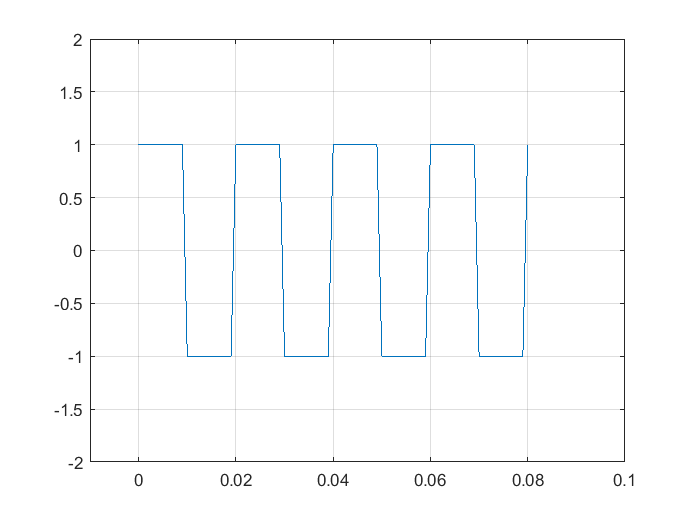

x= 0:0.001:0.08;  % sampled at 1KHz => 1/1000=0.001
y= 2*pi*50*x;     % 2*pi*freq*time
plot(x,square(y))
axis([-0.01, 0.1, -2,2])
grid on

**Sawtooth Wave**

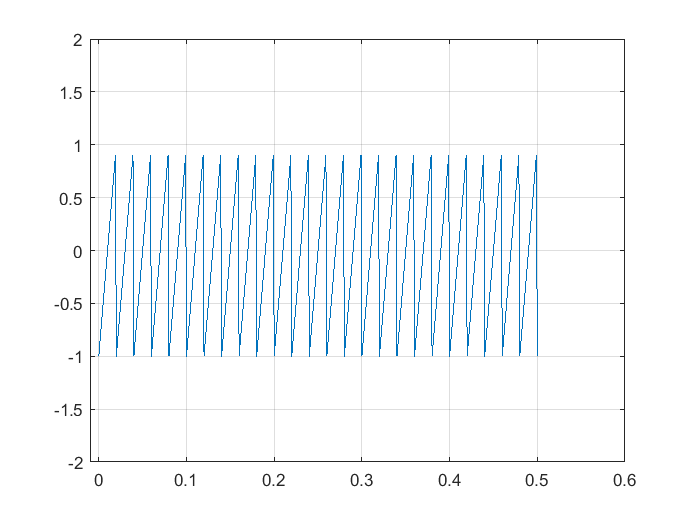

f= 50;  
x= 0:0.001:.5;
y= sawtooth(2*pi*f*x);

plot(x,y)
axis([-0.01, 0.6, -2,2])
grid on

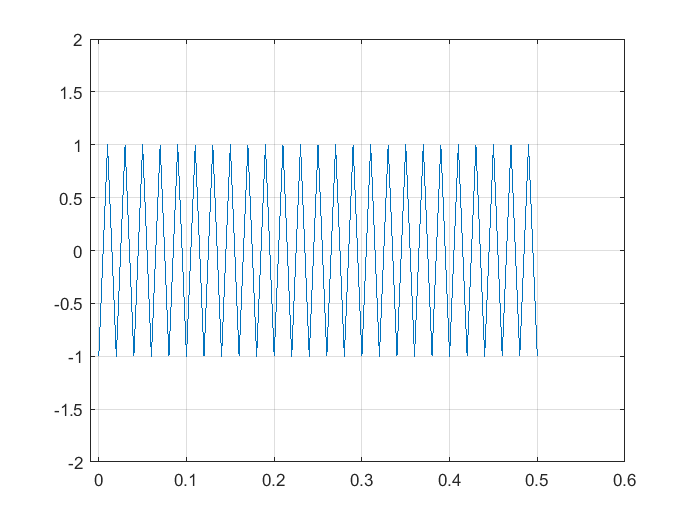

f= 50;  
x= 0:0.001:.5;
y= sawtooth(2*pi*f*x, 0.5); % produces a triangular wave

plot(x,y)
axis([-0.01, 0.6, -2,2])
grid on

**Adding noise to the signal**

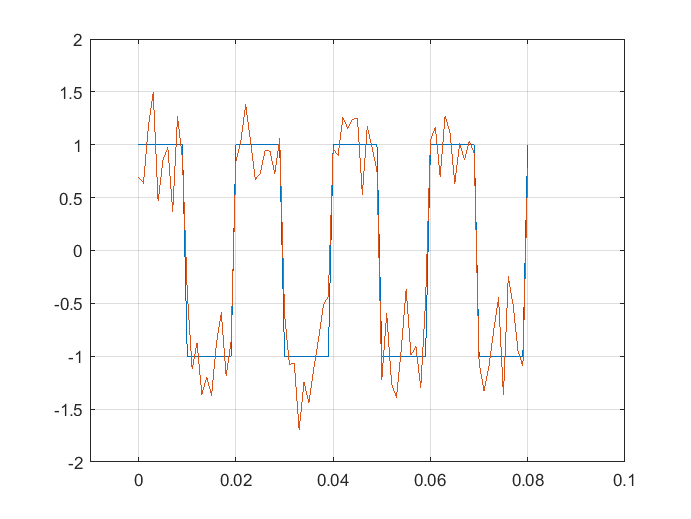

x= 0:0.001:0.08; 
y= square(2*pi*50*x);     
noise = awgn(y,10, 'measured');

plot(x,y, x, noise)
axis([-0.01, 0.1, -2,2])
grid on

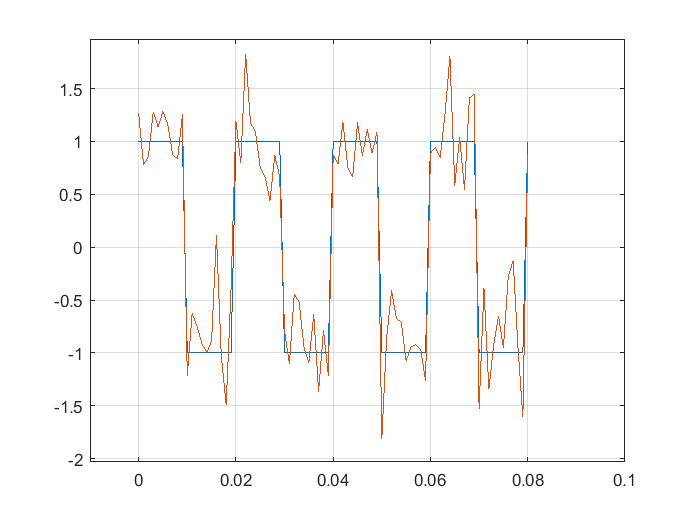

x= 0:0.001:0.08; 
y= square(2*pi*50*x);     
noise = awgn(y,10); %  strength of the signal is 10 times higher than the strength of the noise

plot(x,y, x, noise)
axis([-0.01, 0.1, -2,2])
grid on

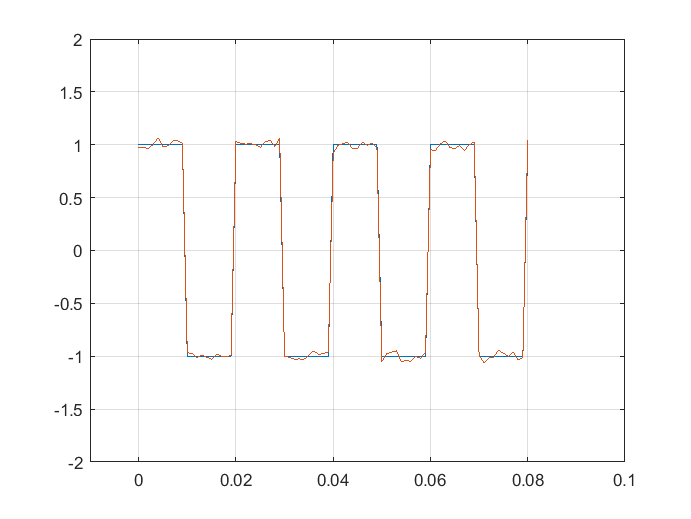

x= 0:0.001:0.08; 
y= square(2*pi*50*x);     
noise = awgn(y,30);

plot(x,y, x, noise)
axis([-0.01, 0.1, -2,2])
grid on

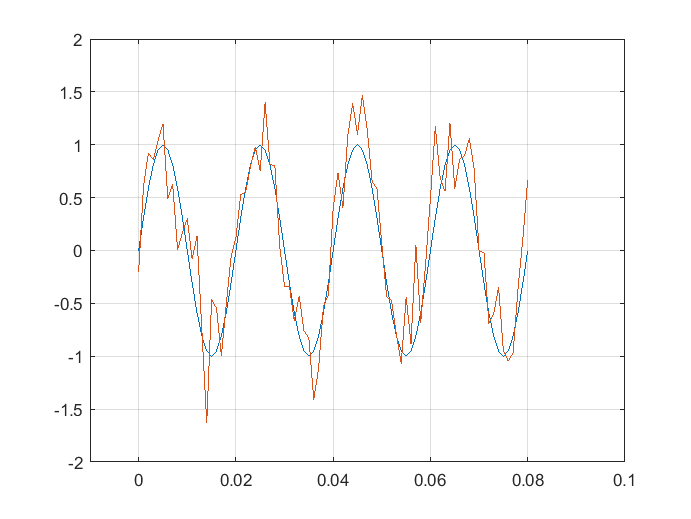

x= 0:0.001:0.08; 
y= sin(2*pi*50*x);     
noise = awgn(y,10);

plot(x,y, x, noise)
axis([-0.01, 0.1, -2,2])
grid on

**Gaussian Pulse**

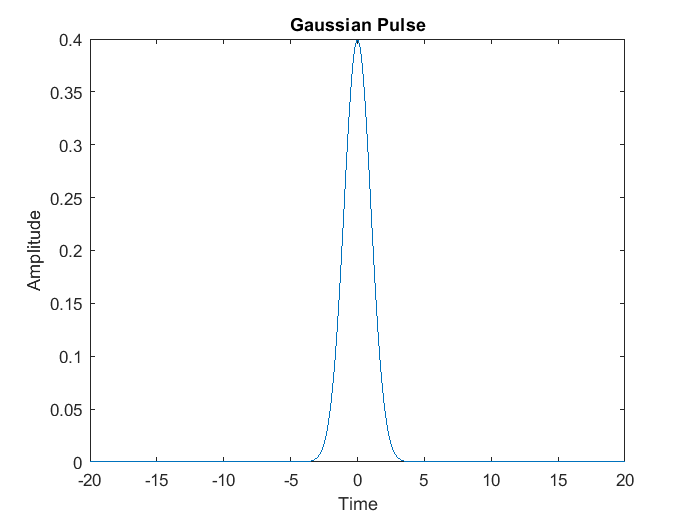

t = -20:0.01:20;      % Time vector
mu = 0;             % Mean of the Gaussian pulse
sigma = 1;          % Standard deviation of the Gaussian pulse

% Generate Gaussian pulse
gaussian_pulse_1 = normpdf(t, mu, sigma);

% Plot the Gaussian pulse
plot(t, gaussian_pulse_1);
title('Gaussian Pulse');
xlabel('Time');
ylabel('Amplitude');

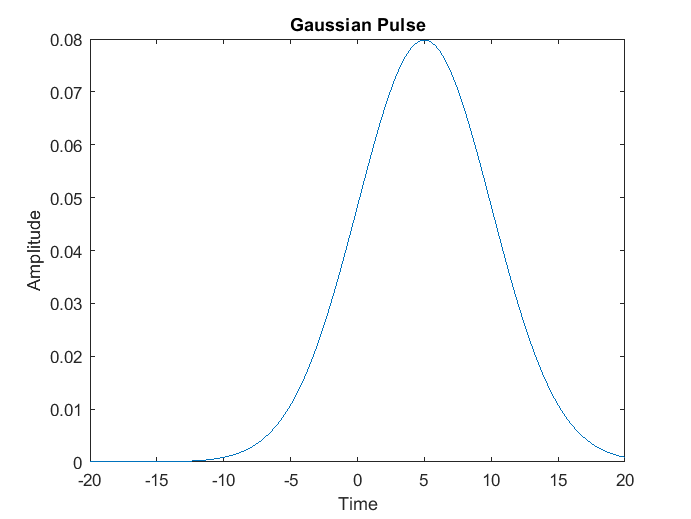

t = -20:0.01:20;      % Time vector
mu = 5;             % Mean of the Gaussian pulse
sigma = 5;          % Standard deviation of the Gaussian pulse

% Generate Gaussian pulse
gaussian_pulse_2 = normpdf(t, mu, sigma);

% Plot the Gaussian pulse
plot(t, gaussian_pulse_2);
title('Gaussian Pulse');
xlabel('Time');
ylabel('Amplitude');

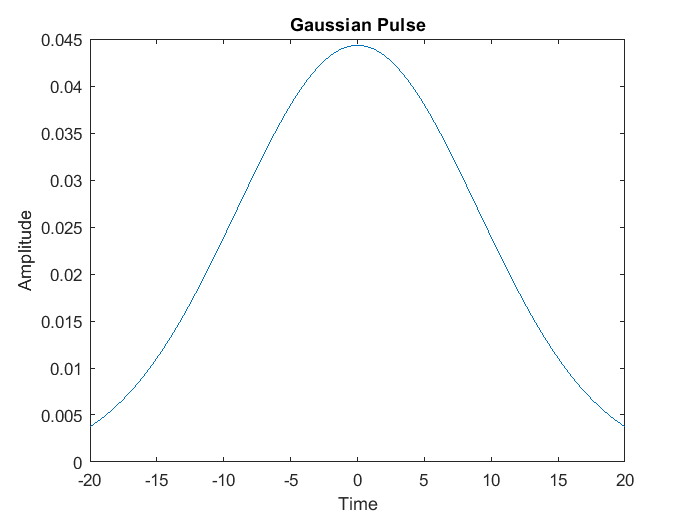

t = -20:0.01:20;      % Time vector
mu = 0;             % Mean of the Gaussian pulse
sigma = 9;          % Standard deviation of the Gaussian pulse

% Generate Gaussian pulse
gaussian_pulse_3 = normpdf(t, mu, sigma);

% Plot the Gaussian pulse
plot(t, gaussian_pulse_3);
title('Gaussian Pulse');
xlabel('Time');
ylabel('Amplitude');

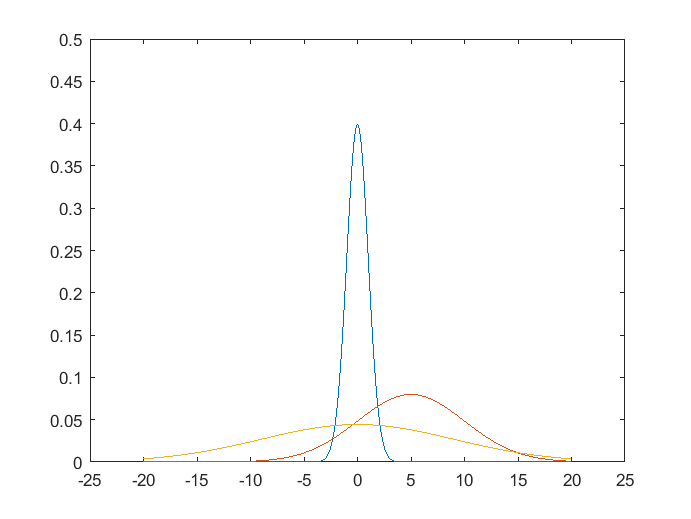

plot(t, gaussian_pulse_1, t, gaussian_pulse_2, t, gaussian_pulse_3)
axis([-25, 25, 0,0.5])

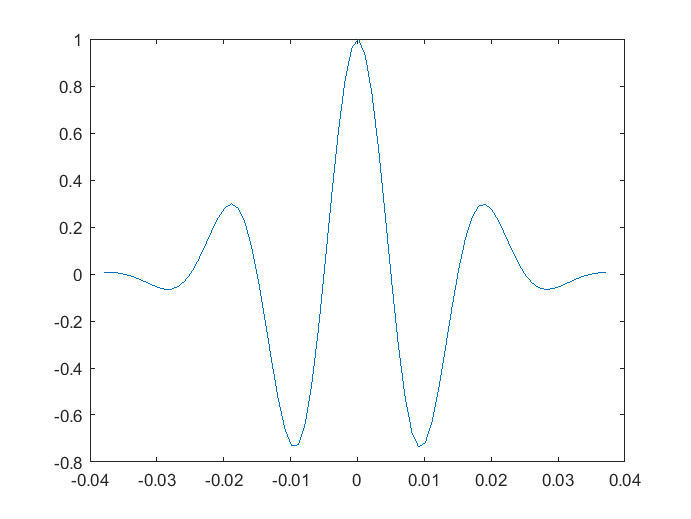

tc = gauspuls("cutoff",50e3,0.6,[],-40);
t1 = -tc : 1e-6 : tc; 
y1 = gauspuls(t1,50e3,0.6);
plot(t1*1e3,y1)

**Creating a pulse train**

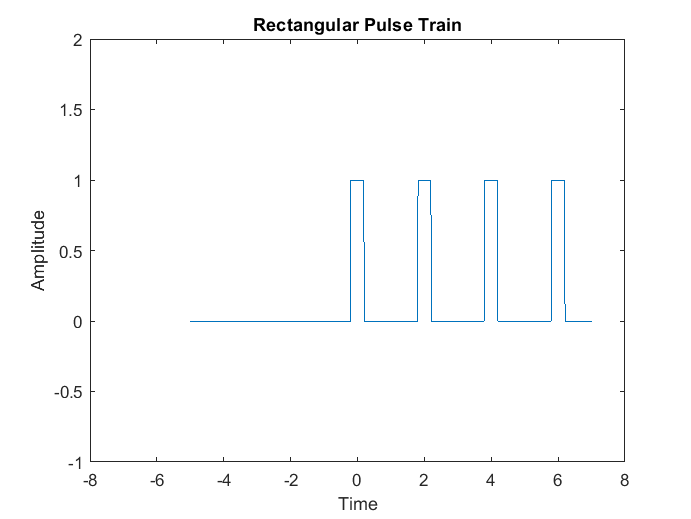

T = 2;                  % Period of the pulse train
pulse_duration = 0.4;   % Duration of each pulse
t = linspace(-5, 7, 1000);  % Time vector

% Generate rectangular pulse train
x = pulstran(t, 0: T: 7, 'rectpuls', pulse_duration);

% Plot the pulse train
plot(t, x);
title('Rectangular Pulse Train');
xlabel('Time');
ylabel('Amplitude');
axis([-8,8,-1,2])
axis on

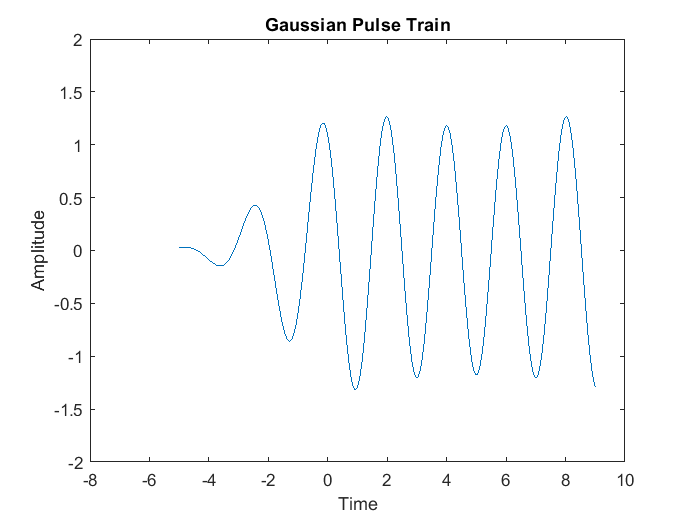

T = 2;                  % Period of the pulse train
pulse_duration = 0.4;   % Duration of each pulse
t = linspace(-5, 9, 1000);  % Time vector

% Generate rectangular pulse train
x = pulstran(t, 0: T: 10, 'gauspuls', pulse_duration);

% Plot the pulse train
plot(t, x);
title('Gaussian Pulse Train');
xlabel('Time');
ylabel('Amplitude');
axis([-8,10,-2,2])
axis on